%Amul Neupane
%CV
%assignment02


%Qno2
%Grayscale image compression


## `%input image`

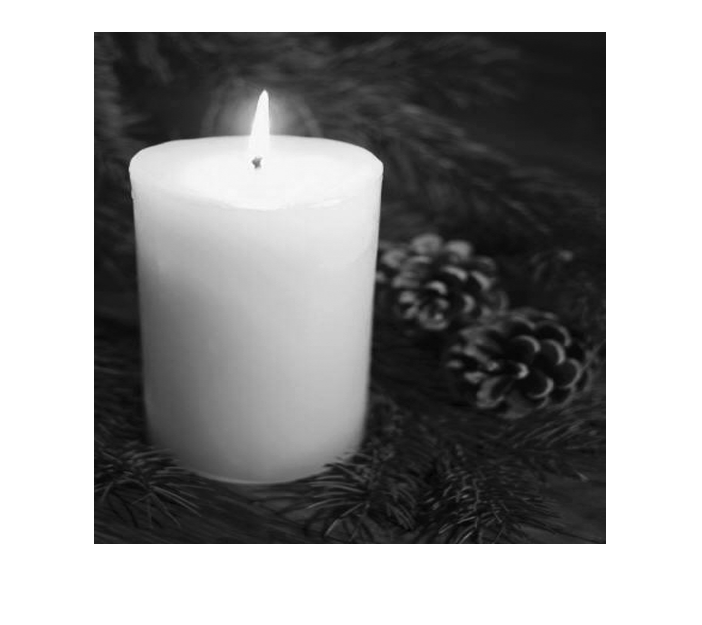

a=imread('1.bmp');
imshow(a,[])


b=zeros(size(a));
kk=1;

## %blocking

sizeblock=8;
k=[1 :sizeblock];
qz=8;

## %compression factor

cf=2;

## %compression function

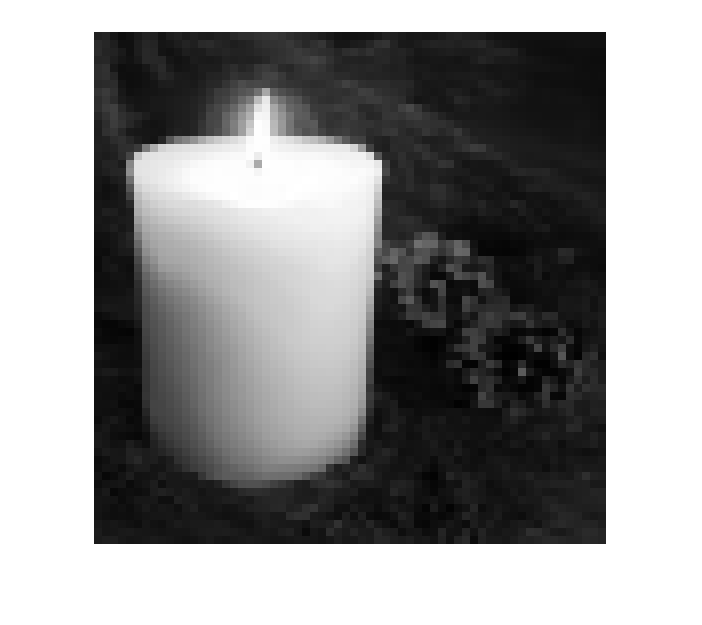

for i=1:(size(a,2)/sizeblock)
    for j=1:(size(a,1)/sizeblock)
        
     xx=a(k +(i-1)*sizeblock, k+(j-1)*sizeblock);
     yy=dct2(xx);
     
     xy=yy;
     for ii=1:sizeblock
              for jj=1:sizeblock

     if (ii+jj)>cf
       yy(ii,jj)=0;
       yy2=yy;
     end
              end
     end
    
     yy=idct2(yy2);
     
    b(k +(i-1)*sizeblock, k+(j-1)*sizeblock)=yy;
     kk=kk+1;
    end
end

imshow(b,[])